clear
clc


% Groups
% 1: 6-OHDA
% 2: Control

M01 = load("Monster1_01_processed.mat"); M01.animal_group = 1;
M02 = load("Monster1_02_processed.mat"); M02.animal_group = 2;
M03 = load("Monster1_03_processed.mat"); M03.animal_group = 1;
M04 = load("Monster1_04_processed.mat"); M04.animal_group = 2;
M05 = load("Monster1_05_processed.mat"); M05.animal_group = 2;
M06 = load("Monster1_06_processed.mat"); M06.animal_group = 1;

exp_name = "Monster1";
animals = [M01 M02 M03 M04 M05 M06];
legends = ["M01" "M02" "M03" "M04" "M05" "M06"];


# 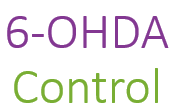

## Trial Duration

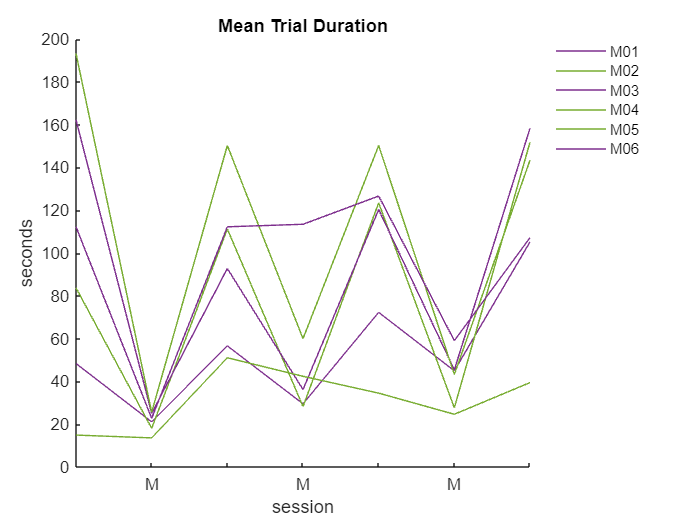

figure
hold on

for i=1:length(animals)
    plotgroup(animals(i), animals(i).mean_trial_duration_vector)
end 

title("Mean Trial Duration")
create_leg(legends)
hold off

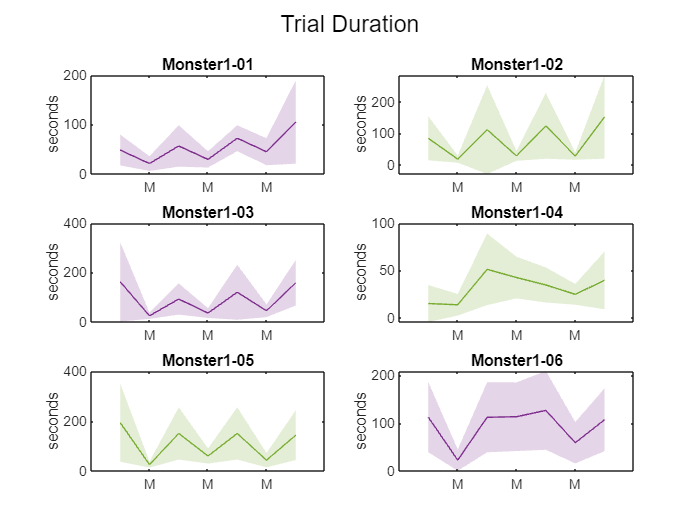

figure

for i=1:length(animals)
    plot_mean_and_shaded_std(i, exp_name + "-0" + string(i), animals(i).mean_trial_duration_vector, animals(i).std_trial_duration_vector, animals(i).animal_group)
end

sgtitle("Trial Duration")

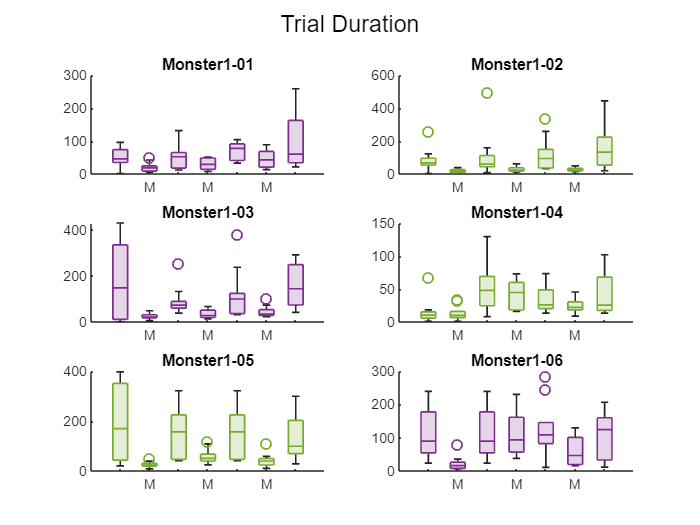

figure 

for i=1:length(animals)
    plot_boxplot_across_sessions(i, exp_name + "-0" + string(i), animals(i).full_trial_duration_vector, animals(i).animal_group)
end

sgtitle("Trial Duration")

## Latency to Enter

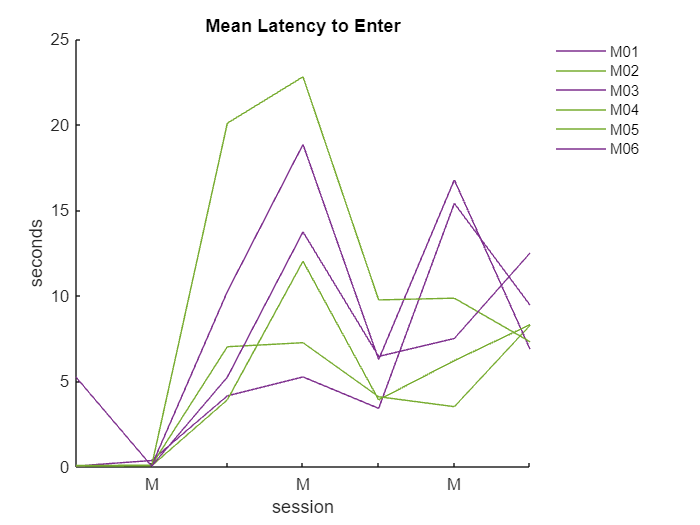

figure 
hold on

for i=1:length(animals)
    plotgroup(animals(i), animals(i).mean_latency_to_enter_vector)
end 

title("Mean Latency to Enter")
create_leg(legends)
hold off

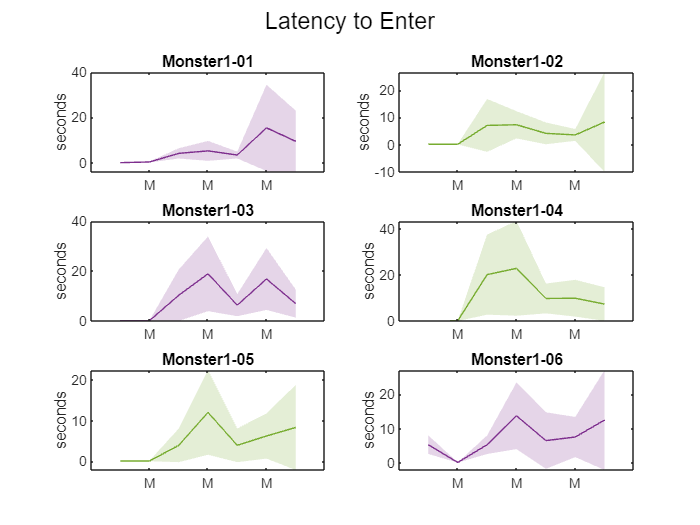

figure

for i=1:length(animals)
    plot_mean_and_shaded_std(i, exp_name + "-0" + string(i), animals(i).mean_latency_to_enter_vector, animals(i).std_latency_to_enter_vector, animals(i).animal_group)
end

sgtitle("Latency to Enter")

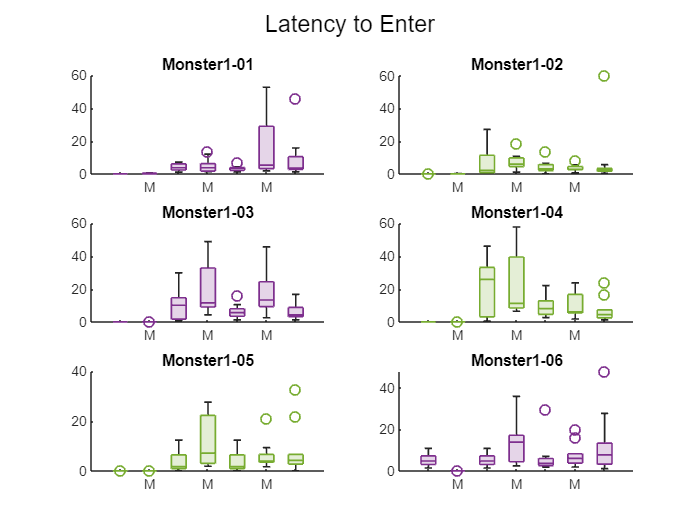

figure 

for i=1:length(animals)
    plot_boxplot_across_sessions(i, exp_name + "-0" + string(i), animals(i).full_latency_to_enter_vector, animals(i).animal_group)
end

sgtitle("Latency to Enter")

## Latency to Trigger

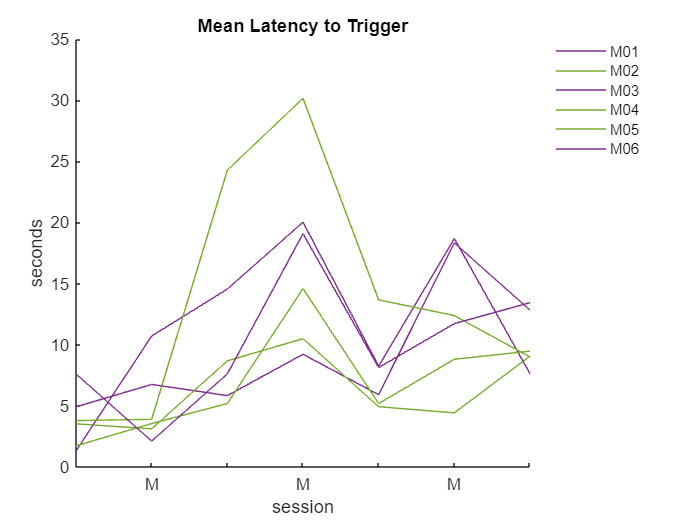

figure 
hold on

for i=1:length(animals)
    plotgroup(animals(i), animals(i).mean_latency_to_trigger_vector)
end 

title("Mean Latency to Trigger")
create_leg(legends)
hold off

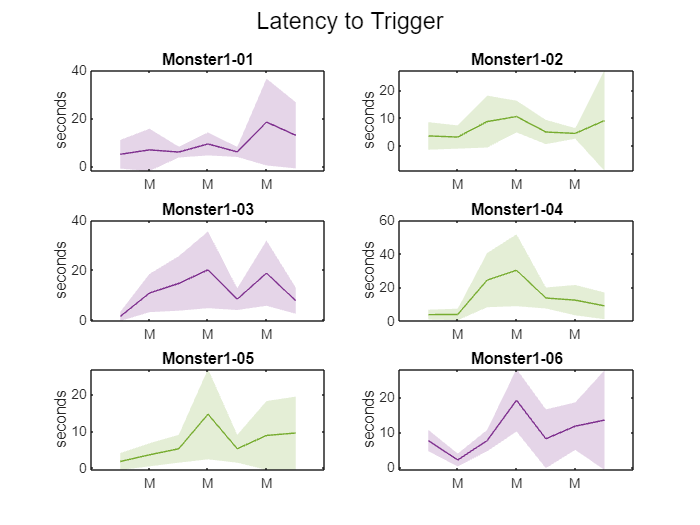

figure

for i=1:length(animals)
    plot_mean_and_shaded_std(i, exp_name + "-0" + string(i), animals(i).mean_latency_to_trigger_vector, animals(i).std_latency_to_trigger_vector, animals(i).animal_group)
end

sgtitle("Latency to Trigger")

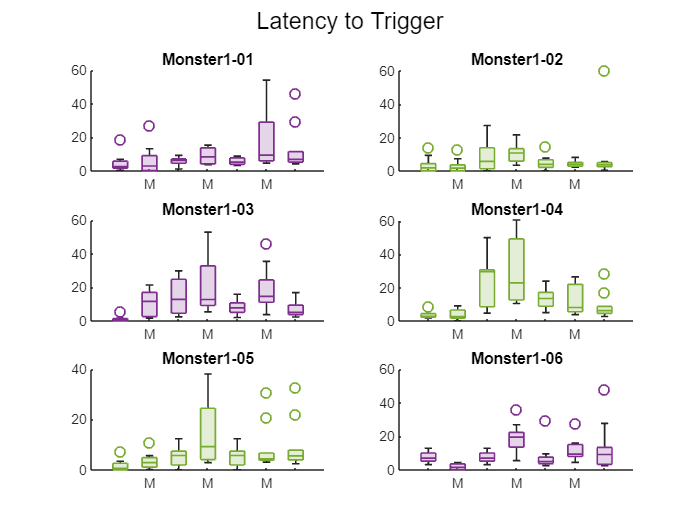

figure 

for i=1:length(animals)
    plot_boxplot_across_sessions(i, exp_name + "-0" + string(i), animals(i).full_latency_to_trigger_vector, animals(i).animal_group)
end

sgtitle("Latency to Trigger")

## Latency to Lick

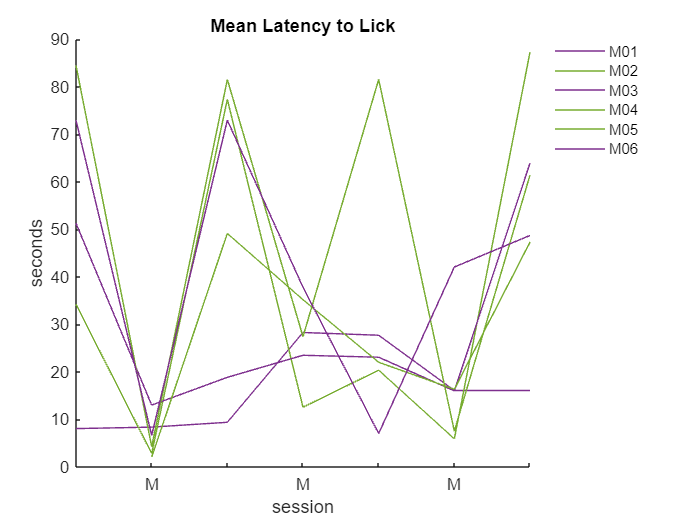

figure 
hold on

for i=1:length(animals)
    plotgroup(animals(i), animals(i).mean_latency_to_lick_vector)
end 

title("Mean Latency to Lick")
create_leg(legends)
hold off

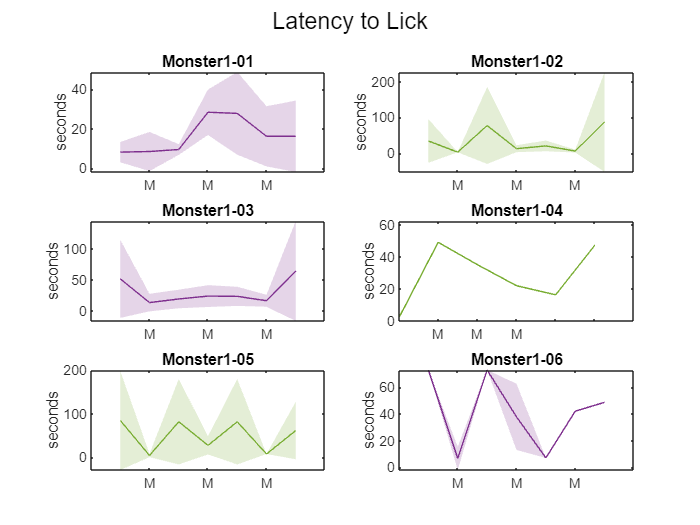

figure

for i=1:length(animals)
    plot_mean_and_shaded_std(i, exp_name + "-0" + string(i), animals(i).mean_latency_to_lick_vector, animals(i).std_latency_to_lick_vector, animals(i).animal_group)
end

sgtitle("Latency to Lick")

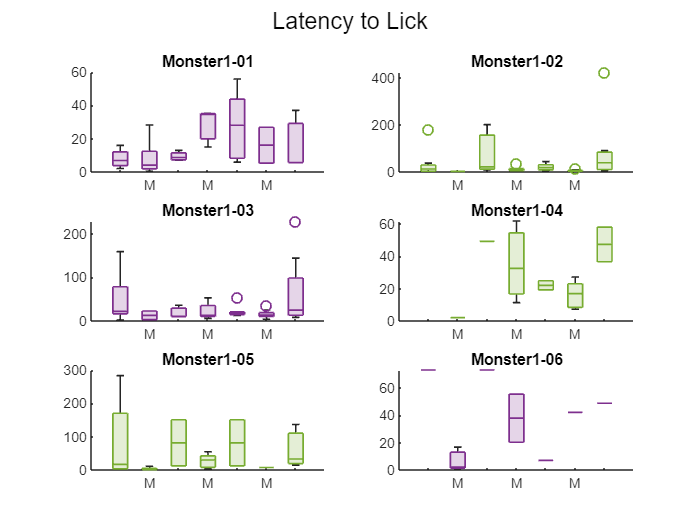

figure 

for i=1:length(animals)
    plot_boxplot_across_sessions(i, exp_name + "-0" + string(i), animals(i).full_latency_to_lick_vector, animals(i).animal_group)
end

sgtitle("Latency to Lick")

## Escape Duration

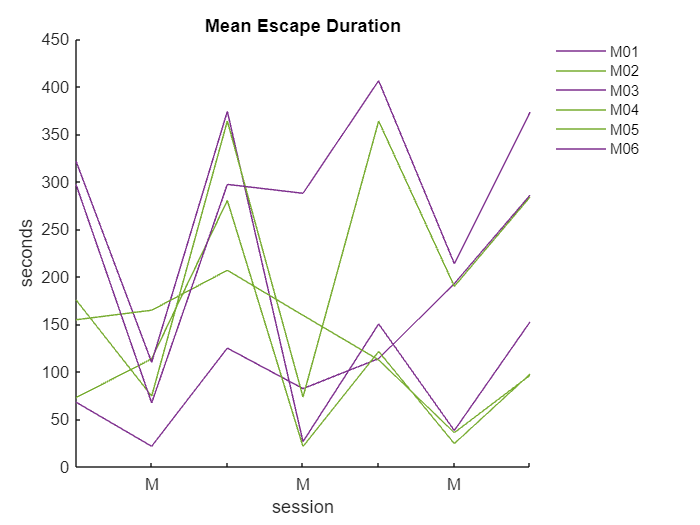

figure 
hold on

for i=1:length(animals)
    plotgroup(animals(i), animals(i).mean_escape_duration_vector)
end 

title("Mean Escape Duration")
create_leg(legends)
hold off

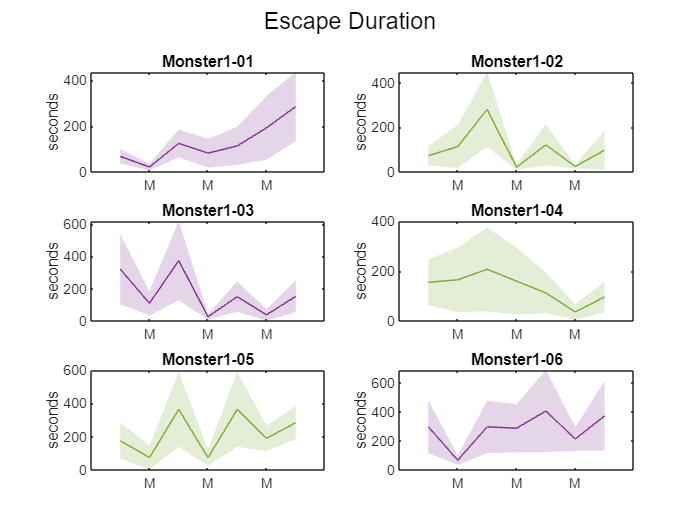

figure

for i=1:length(animals)
    plot_mean_and_shaded_std(i, exp_name + "-0" + string(i), animals(i).mean_escape_duration_vector, animals(i).std_escape_duration_vector, animals(i).animal_group)
end

sgtitle("Escape Duration")

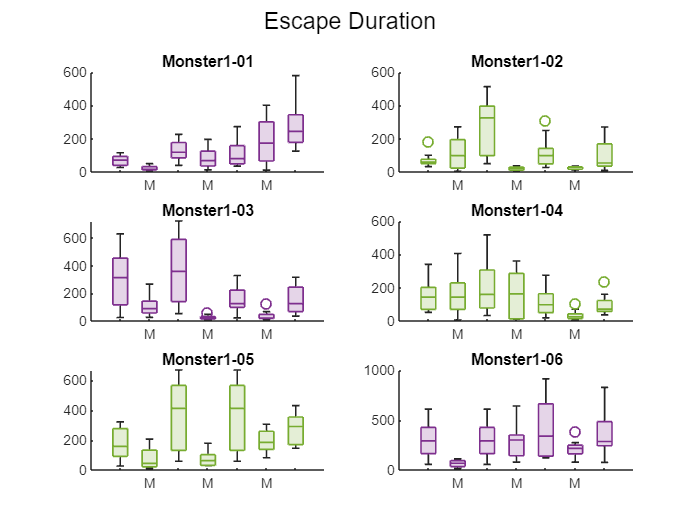

figure 

for i=1:length(animals)
    plot_boxplot_across_sessions(i, exp_name + "-0" + string(i), animals(i).full_escape_duration_vector, animals(i).animal_group)
end

sgtitle("Escape Duration")

________________________________

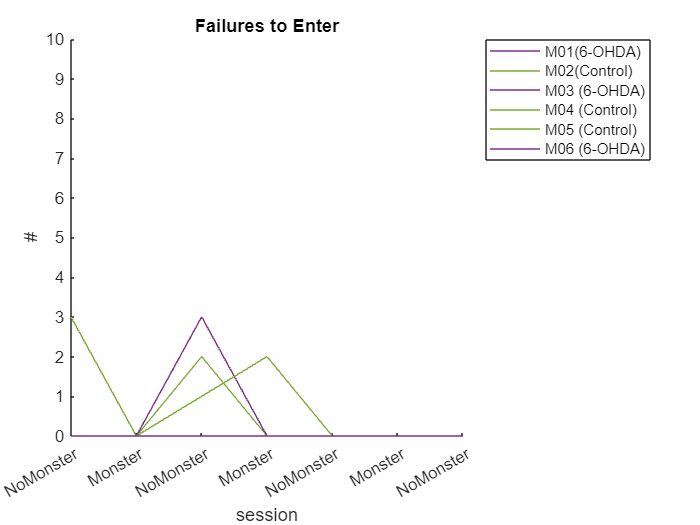

figure
hold on
plotgroup(M01, M01.failed_to_enter_sum_vector)
plotgroup(M02, M02.failed_to_enter_sum_vector)
plotgroup(M03, M03.failed_to_enter_sum_vector)
plotgroup(M04, M04.failed_to_enter_sum_vector)
plotgroup(M05, M05.failed_to_enter_sum_vector)
plotgroup(M06, M06.failed_to_enter_sum_vector)
title("Failures to Enter")
ylabel("#")
xlabel("session")
ylim([0 10])
legend(["M01(6-OHDA)" "M02(Control)" "M03 (6-OHDA)" "M04 (Control)" "M05 (Control)" "M06 (6-OHDA)"], "Location","northeastoutside")
xticklabels(["NoMonster" "Monster" "NoMonster" "Monster" "NoMonster" "Monster" "NoMonster"])
hold off

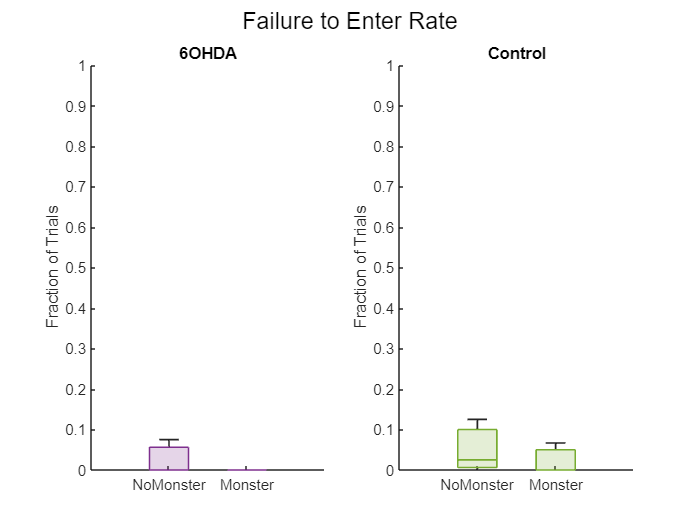

figure
exp_no_monster_failed_to_enter = [
    M01.failed_to_enter_no_monster_rate
    M03.failed_to_enter_no_monster_rate
    M06.failed_to_enter_no_monster_rate
];

exp_monster_failed_to_enter = [
    M01.failed_to_enter_monster_rate
    M03.failed_to_enter_monster_rate
    M06.failed_to_enter_monster_rate
];

control_no_monster_failed_to_enter = [
    M02.failed_to_enter_no_monster_rate
    M04.failed_to_enter_no_monster_rate
    M05.failed_to_enter_no_monster_rate
];

control_monster_failed_to_enter = [
    M02.failed_to_enter_monster_rate
    M04.failed_to_enter_monster_rate
    M05.failed_to_enter_monster_rate
];

exp_failed_to_enter_summary = [
    exp_no_monster_failed_to_enter, ...
    exp_monster_failed_to_enter, ...
];

control_trial_duration_summary = [
    control_no_monster_failed_to_enter, ...
    control_monster_failed_to_enter, ...
];

subplot(1,2,1)
trial_duration_exp = boxchart(exp_failed_to_enter_summary);
trial_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
trial_duration_control = boxchart(control_trial_duration_summary);
trial_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

sgtitle("Failure to Enter Rate")

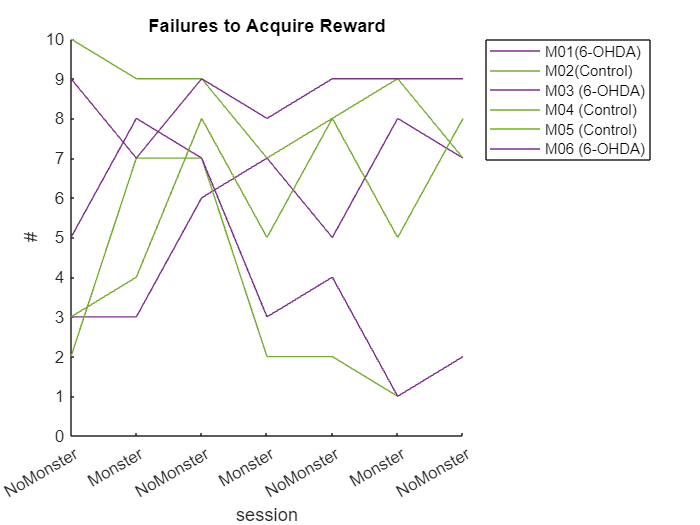

figure
hold on
plotgroup(M01, M01.failed_to_lick_sum_vector)
plotgroup(M02, M02.failed_to_lick_sum_vector)
plotgroup(M03, M03.failed_to_lick_sum_vector)
plotgroup(M04, M04.failed_to_lick_sum_vector)
plotgroup(M05, M05.failed_to_lick_sum_vector)
plotgroup(M06, M06.failed_to_lick_sum_vector)
title("Failures to Acquire Reward")
ylabel("#")
xlabel("session")
ylim([0 10])
legend(["M01(6-OHDA)" "M02(Control)" "M03 (6-OHDA)" "M04 (Control)" "M05 (Control)" "M06 (6-OHDA)"], "Location","northeastoutside")
xticklabels(["NoMonster" "Monster" "NoMonster" "Monster" "NoMonster" "Monster" "NoMonster"])
hold off

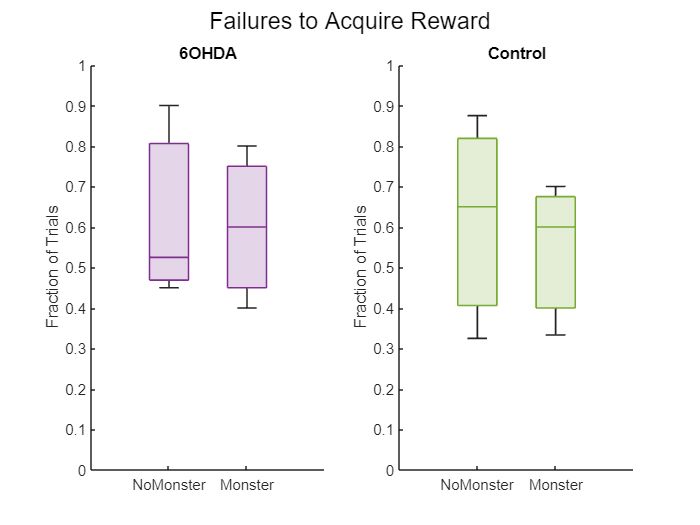

figure
exp_no_monster_failed_to_lick = [
    M01.failed_to_lick_no_monster_rate
    M03.failed_to_lick_no_monster_rate
    M06.failed_to_lick_no_monster_rate
];

exp_monster_failed_to_lick = [
    M01.failed_to_lick_monster_rate
    M03.failed_to_lick_monster_rate
    M06.failed_to_lick_monster_rate
];

control_no_monster_failed_to_lick = [
    M02.failed_to_lick_no_monster_rate
    M04.failed_to_lick_no_monster_rate
    M05.failed_to_lick_no_monster_rate
];

control_monster_failed_to_lick = [
    M02.failed_to_lick_monster_rate
    M04.failed_to_lick_monster_rate
    M05.failed_to_lick_monster_rate
];

exp_failed_to_lick_summary = [
    exp_no_monster_failed_to_lick, ...
    exp_monster_failed_to_lick, ...
];

control_failed_to_lick_summary = [
    control_no_monster_failed_to_lick, ...
    control_monster_failed_to_lick, ...
];

subplot(1,2,1)
trial_duration_exp = boxchart(exp_failed_to_lick_summary);
trial_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
trial_duration_control = boxchart(control_failed_to_lick_summary);
trial_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

sgtitle("Failures to Acquire Reward")

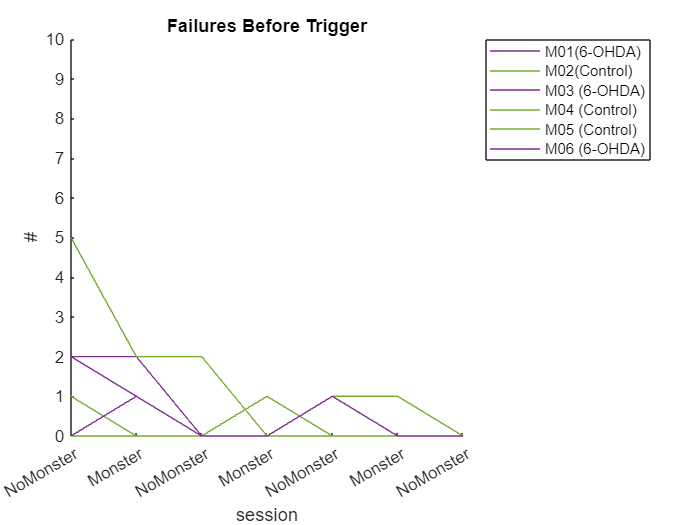

figure
hold on
plotgroup(M01, M01.failed_before_trigger_sum_vector)
plotgroup(M02, M02.failed_before_trigger_sum_vector)
plotgroup(M03, M03.failed_before_trigger_sum_vector)
plotgroup(M04, M04.failed_before_trigger_sum_vector)
plotgroup(M05, M05.failed_before_trigger_sum_vector)
plotgroup(M06, M06.failed_before_trigger_sum_vector)
title("Failures Before Trigger")
ylabel("#")
xlabel("session")
ylim([0 10])
legend(["M01(6-OHDA)" "M02(Control)" "M03 (6-OHDA)" "M04 (Control)" "M05 (Control)" "M06 (6-OHDA)"], "Location","northeastoutside")
xticklabels(["NoMonster" "Monster" "NoMonster" "Monster" "NoMonster" "Monster" "NoMonster"])
hold off

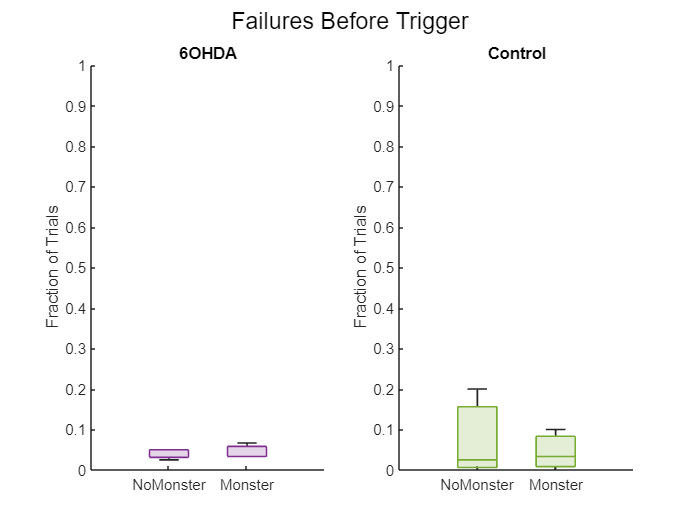

figure
exp_no_monster_failed_before_trigger = [
    M01.failed_before_trigger_no_monster_rate
    M03.failed_before_trigger_no_monster_rate
    M06.failed_before_trigger_no_monster_rate
];

exp_monster_failed_before_trigger = [
    M01.failed_before_trigger_monster_rate
    M03.failed_before_trigger_monster_rate
    M06.failed_before_trigger_monster_rate
];

control_no_monster_failed_before_trigger = [
    M02.failed_before_trigger_no_monster_rate
    M04.failed_before_trigger_no_monster_rate
    M05.failed_before_trigger_no_monster_rate
];

control_monster_failed_before_trigger = [
    M02.failed_before_trigger_monster_rate
    M04.failed_before_trigger_monster_rate
    M05.failed_before_trigger_monster_rate
];

exp_failed_before_trigger_summary = [
    exp_no_monster_failed_before_trigger, ...
    exp_monster_failed_before_trigger, ...
];

control_failed_before_trigger_summary = [
    control_no_monster_failed_before_trigger, ...
    control_monster_failed_before_trigger, ...
];

subplot(1,2,1)
trial_duration_exp = boxchart(exp_failed_before_trigger_summary);
trial_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
trial_duration_control = boxchart(control_failed_before_trigger_summary);
trial_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

sgtitle("Failures Before Trigger")

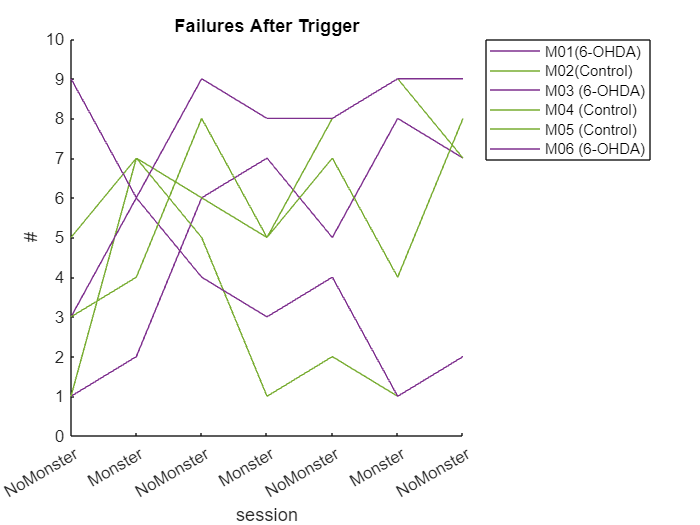

figure
hold on
plotgroup(M01, M01.failed_after_trigger_sum_vector)
plotgroup(M02, M02.failed_after_trigger_sum_vector)
plotgroup(M03, M03.failed_after_trigger_sum_vector)
plotgroup(M04, M04.failed_after_trigger_sum_vector)
plotgroup(M05, M05.failed_after_trigger_sum_vector)
plotgroup(M06, M06.failed_after_trigger_sum_vector)
title("Failures After Trigger")
ylabel("#")
xlabel("session")
ylim([0 10])
legend(["M01(6-OHDA)" "M02(Control)" "M03 (6-OHDA)" "M04 (Control)" "M05 (Control)" "M06 (6-OHDA)"], "Location","northeastoutside")
xticklabels(["NoMonster" "Monster" "NoMonster" "Monster" "NoMonster" "Monster" "NoMonster"])
hold off

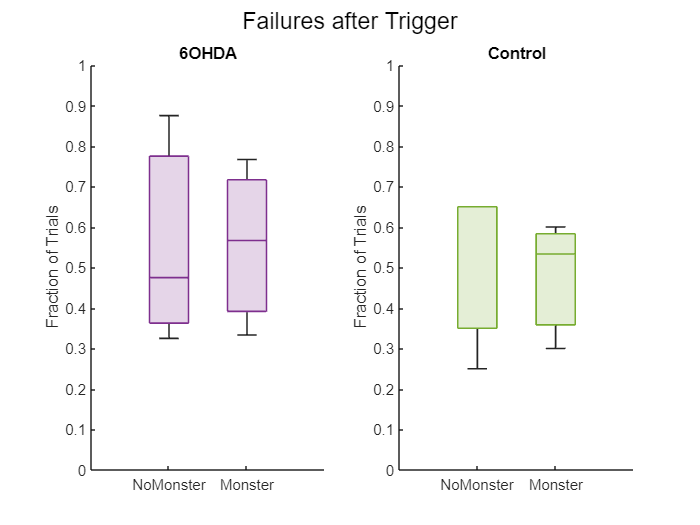

figure
exp_no_monster_failed_after_trigger = [
    M01.failed_after_trigger_no_monster_rate
    M03.failed_after_trigger_no_monster_rate
    M06.failed_after_trigger_no_monster_rate
];

exp_monster_failed_after_trigger = [
    M01.failed_after_trigger_monster_rate
    M03.failed_after_trigger_monster_rate
    M06.failed_after_trigger_monster_rate
];

control_no_monster_failed_after_trigger = [
    M02.failed_after_trigger_no_monster_rate
    M04.failed_after_trigger_no_monster_rate
    M05.failed_after_trigger_no_monster_rate
];

control_monster_failed_after_trigger = [
    M02.failed_after_trigger_monster_rate
    M04.failed_after_trigger_monster_rate
    M05.failed_after_trigger_monster_rate
];

exp_failed_after_trigger_summary = [
    exp_no_monster_failed_after_trigger, ...
    exp_monster_failed_after_trigger, ...
];

control_failed_after_trigger_summary = [
    control_no_monster_failed_after_trigger, ...
    control_monster_failed_after_trigger, ...
];

subplot(1,2,1)
trial_duration_exp = boxchart(exp_failed_after_trigger_summary);
trial_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
trial_duration_control = boxchart(control_failed_after_trigger_summary);
trial_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Fraction of Trials")
ylim([0 1])
xticklabels(["NoMonster" "Monster"])

sgtitle("Failures after Trigger")

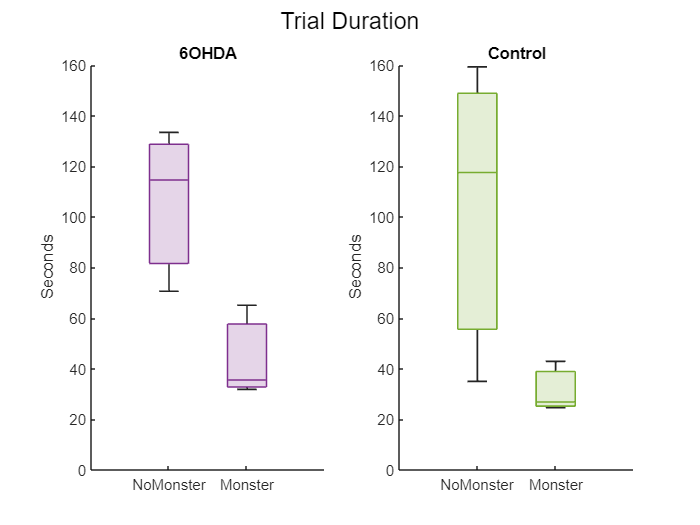

figure
exp_no_monster_trial_duration = [
    M01.no_monster_mean_trial_duration
    M03.no_monster_mean_trial_duration
    M06.no_monster_mean_trial_duration
];

exp_monster_trial_duration = [
    M01.monster_mean_trial_duration
    M03.monster_mean_trial_duration
    M06.monster_mean_trial_duration
];

control_no_monster_trial_duration = [
    M02.no_monster_mean_trial_duration
    M04.no_monster_mean_trial_duration
    M05.no_monster_mean_trial_duration
];

control_monster_trial_duration = [
    M02.monster_mean_trial_duration
    M04.monster_mean_trial_duration
    M05.monster_mean_trial_duration
];

exp_trial_duration_summary = [
    exp_no_monster_trial_duration, ...
    exp_monster_trial_duration, ...
];

control_trial_duration_summary = [
    control_no_monster_trial_duration, ...
    control_monster_trial_duration, ...
];

subplot(1,2,1)
trial_duration_exp = boxchart(exp_trial_duration_summary);
trial_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
trial_duration_control = boxchart(control_trial_duration_summary);
trial_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

sgtitle("Trial Duration")

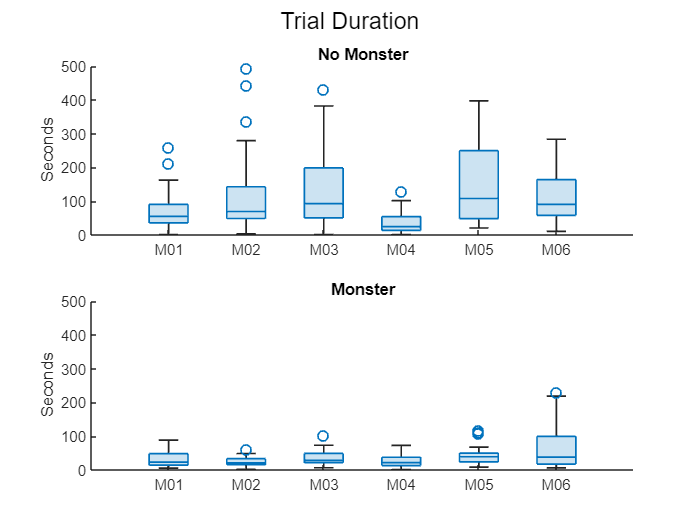

figure
no_monster_trial_duration_per_animal = [
    M01.no_monster_trial_duration_all, ...
    M02.no_monster_trial_duration_all, ...
    M03.no_monster_trial_duration_all, ...
    M04.no_monster_trial_duration_all, ...
    M05.no_monster_trial_duration_all, ...
    M06.no_monster_trial_duration_all
];

monster_trial_duration_per_animal = [
    M01.monster_trial_duration_all, ...
    M02.monster_trial_duration_all, ...
    M03.monster_trial_duration_all, ...
    M04.monster_trial_duration_all, ...
    M05.monster_trial_duration_all, ...
    M06.monster_trial_duration_all
];

subplot(2,1,1)
boxchart(no_monster_trial_duration_per_animal)
title("No Monster")
ylabel("Seconds")
ylim([0 500])
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

subplot(2,1,2)
boxchart(monster_trial_duration_per_animal)
title("Monster")
ylabel("Seconds")
ylim([0 500])
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])
sgtitle("Trial Duration")

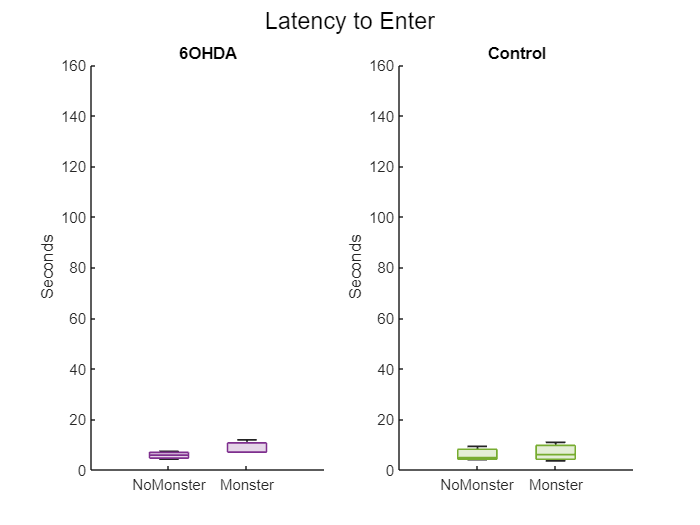

figure
exp_no_monster_latency_to_enter = [
    M01.no_monster_mean_latency_to_enter
    M03.no_monster_mean_latency_to_enter
    M06.no_monster_mean_latency_to_enter
];

exp_monster_latency_to_enter = [
    M01.monster_mean_latency_to_enter
    M03.monster_mean_latency_to_enter
    M06.monster_mean_latency_to_enter
];

control_no_monster_latency_to_enter = [
    M02.no_monster_mean_latency_to_enter
    M04.no_monster_mean_latency_to_enter
    M05.no_monster_mean_latency_to_enter
];

control_monster_latency_to_enter = [
    M02.monster_mean_latency_to_enter
    M04.monster_mean_latency_to_enter
    M05.monster_mean_latency_to_enter
];

exp_latency_to_enter_summary = [
    exp_no_monster_latency_to_enter, ...
    exp_monster_latency_to_enter, ...
];

control_latency_to_enter_summary = [
    control_no_monster_latency_to_enter, ...
    control_monster_latency_to_enter, ...
];

subplot(1,2,1)
latency_to_enter_exp = boxchart(exp_latency_to_enter_summary);
latency_to_enter_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
latency_to_enter_control = boxchart(control_latency_to_enter_summary);
latency_to_enter_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

sgtitle("Latency to Enter")

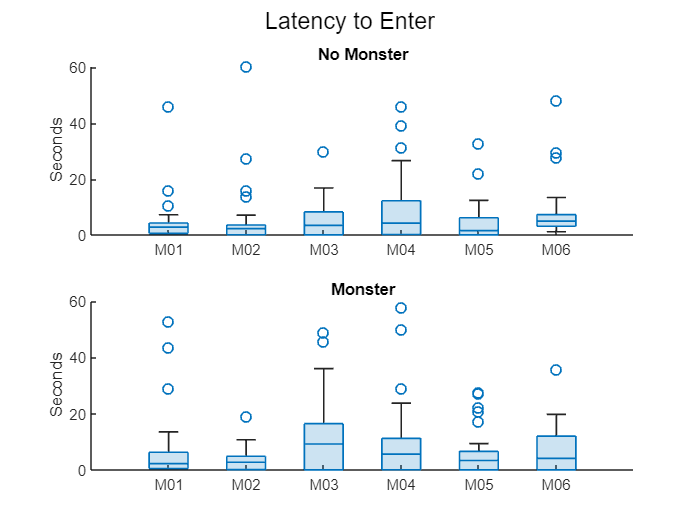

figure
no_monster_latency_to_enter_per_animal = [
    M01.no_monster_latency_to_enter_all, ...
    M02.no_monster_latency_to_enter_all, ...
    M03.no_monster_latency_to_enter_all, ...
    M04.no_monster_latency_to_enter_all, ...
    M05.no_monster_latency_to_enter_all, ...
    M06.no_monster_latency_to_enter_all
];

monster_latency_to_enter_per_animal = [
    M01.monster_latency_to_enter_all, ...
    M02.monster_latency_to_enter_all, ...
    M03.monster_latency_to_enter_all, ...
    M04.monster_latency_to_enter_all, ...
    M05.monster_latency_to_enter_all, ...
    M06.monster_latency_to_enter_all
];

subplot(2,1,1)
boxchart(no_monster_latency_to_enter_per_animal)
title("No Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

subplot(2,1,2)
boxchart(monster_latency_to_enter_per_animal)
title("Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

sgtitle("Latency to Enter")

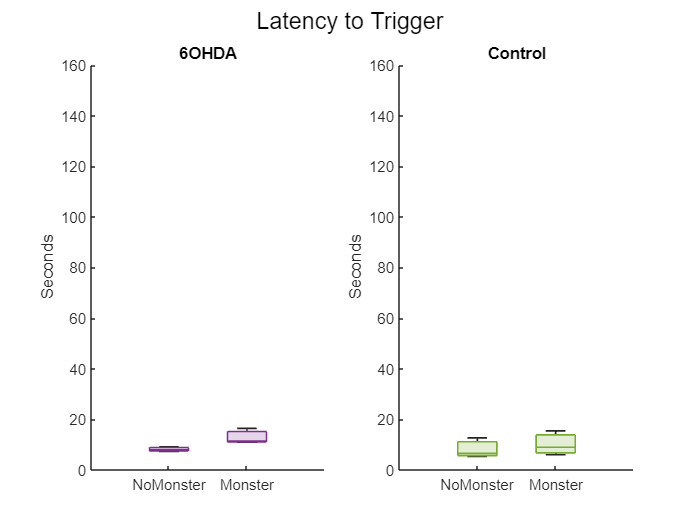

figure
exp_no_monster_latency_to_trigger = [
    M01.no_monster_mean_latency_to_trigger
    M03.no_monster_mean_latency_to_trigger
    M06.no_monster_mean_latency_to_trigger
];

exp_monster_latency_to_trigger = [
    M01.monster_mean_latency_to_trigger
    M03.monster_mean_latency_to_trigger
    M06.monster_mean_latency_to_trigger
];

control_no_monster_latency_to_trigger = [
    M02.no_monster_mean_latency_to_trigger
    M04.no_monster_mean_latency_to_trigger
    M05.no_monster_mean_latency_to_trigger
];

control_monster_latency_to_trigger = [
    M02.monster_mean_latency_to_trigger
    M04.monster_mean_latency_to_trigger
    M05.monster_mean_latency_to_trigger
];

exp_latency_to_trigger_summary = [
    exp_no_monster_latency_to_trigger, ...
    exp_monster_latency_to_trigger, ...
];

control_latency_to_trigger_summary = [
    control_no_monster_latency_to_trigger, ...
    control_monster_latency_to_trigger, ...
];

subplot(1,2,1)
latency_to_trigger_exp = boxchart(exp_latency_to_trigger_summary);
latency_to_trigger_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
latency_to_trigger_control = boxchart(control_latency_to_trigger_summary);
latency_to_trigger_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

sgtitle("Latency to Trigger")

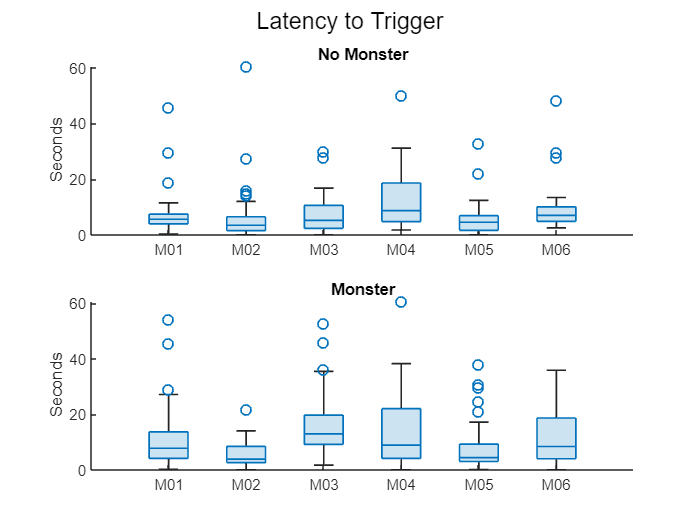

figure
no_monster_latency_to_trigger_per_animal = [
    M01.no_monster_latency_to_trigger_all, ...
    M02.no_monster_latency_to_trigger_all, ...
    M03.no_monster_latency_to_trigger_all, ...
    M04.no_monster_latency_to_trigger_all, ...
    M05.no_monster_latency_to_trigger_all, ...
    M06.no_monster_latency_to_trigger_all
];

monster_latency_to_trigger_per_animal = [
    M01.monster_latency_to_trigger_all, ...
    M02.monster_latency_to_trigger_all, ...
    M03.monster_latency_to_trigger_all, ...
    M04.monster_latency_to_trigger_all, ...
    M05.monster_latency_to_trigger_all, ...
    M06.monster_latency_to_trigger_all
];

subplot(2,1,1)
boxchart(no_monster_latency_to_trigger_per_animal)
title("No Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

subplot(2,1,2)
boxchart(monster_latency_to_trigger_per_animal)
title("Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

sgtitle("Latency to Trigger")

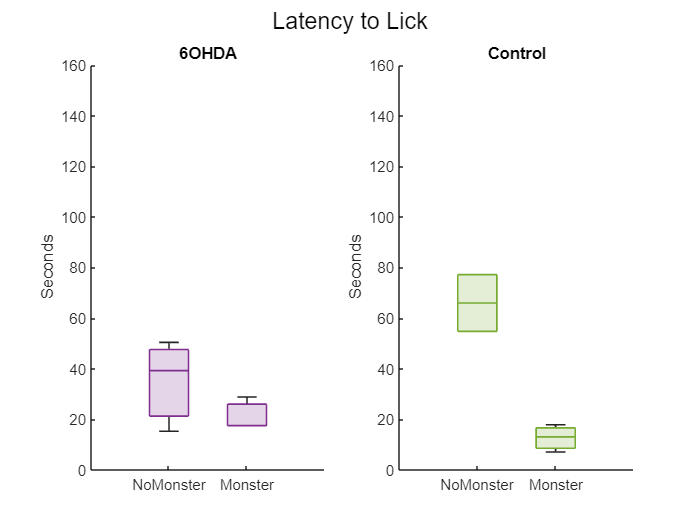

figure
exp_no_monster_latency_to_lick = [
    M01.no_monster_mean_latency_to_lick
    M03.no_monster_mean_latency_to_lick
    M06.no_monster_mean_latency_to_lick
];

exp_monster_latency_to_lick = [
    M01.monster_mean_latency_to_lick
    M03.monster_mean_latency_to_lick
    M06.monster_mean_latency_to_lick
];

control_no_monster_latency_to_lick = [
    M02.no_monster_mean_latency_to_lick
    M04.no_monster_mean_latency_to_lick
    M05.no_monster_mean_latency_to_lick
];

control_monster_latency_to_lick = [
    M02.monster_mean_latency_to_lick
    M04.monster_mean_latency_to_lick
    M05.monster_mean_latency_to_lick
];

exp_latency_to_lick_summary = [
    exp_no_monster_latency_to_lick, ...
    exp_monster_latency_to_lick, ...
];

control_latency_to_lick_summary = [
    control_no_monster_latency_to_lick, ...
    control_monster_latency_to_lick, ...
];

subplot(1,2,1)
latency_to_lick_exp = boxchart(exp_latency_to_lick_summary);
latency_to_lick_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
latency_to_lick_control = boxchart(control_latency_to_lick_summary);
latency_to_lick_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Seconds")
ylim([0 160])
xticklabels(["NoMonster" "Monster"])
sgtitle("Latency to Lick")

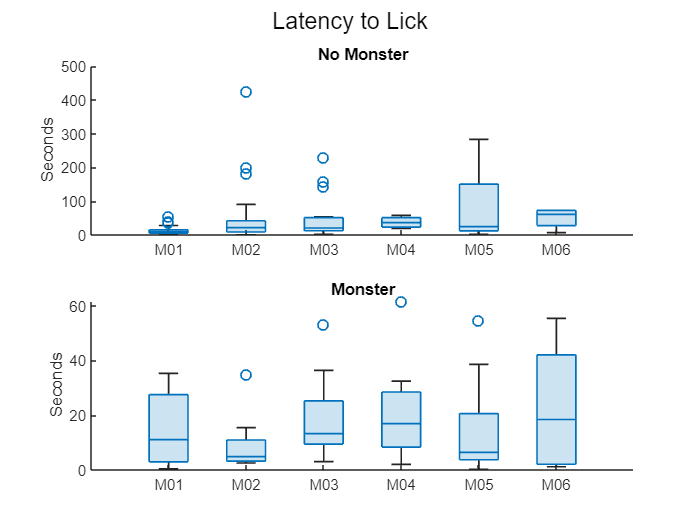

figure
no_monster_latency_to_lick_per_animal = [
    M01.no_monster_latency_to_lick_all, ...
    M02.no_monster_latency_to_lick_all, ...
    M03.no_monster_latency_to_lick_all, ...
    M04.no_monster_latency_to_lick_all, ...
    M05.no_monster_latency_to_lick_all, ...
    M06.no_monster_latency_to_lick_all
];

monster_latency_to_lick_per_animal = [
    M01.monster_latency_to_lick_all, ...
    M02.monster_latency_to_lick_all, ...
    M03.monster_latency_to_lick_all, ...
    M04.monster_latency_to_lick_all, ...
    M05.monster_latency_to_lick_all, ...
    M06.monster_latency_to_lick_all
];

subplot(2,1,1)
boxchart(no_monster_latency_to_lick_per_animal)
title("No Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

subplot(2,1,2)
boxchart(monster_latency_to_lick_per_animal)
title("Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

sgtitle("Latency to Lick")

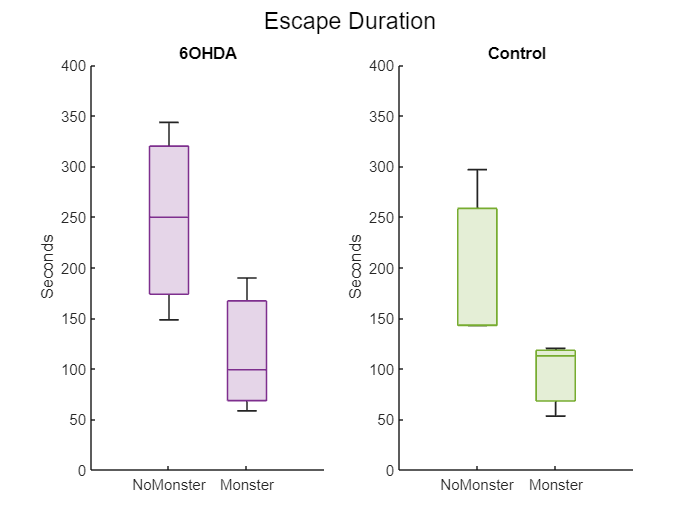

figure
exp_no_monster_escape_duration = [
    M01.no_monster_mean_escape_duration
    M03.no_monster_mean_escape_duration
    M06.no_monster_mean_escape_duration
];

exp_monster_escape_duration = [
    M01.monster_mean_escape_duration
    M03.monster_mean_escape_duration
    M06.monster_mean_escape_duration
];

control_no_monster_escape_duration = [
    M02.no_monster_mean_escape_duration
    M04.no_monster_mean_escape_duration
    M05.no_monster_mean_escape_duration
];

control_monster_escape_duration = [
    M02.monster_mean_escape_duration
    M04.monster_mean_escape_duration
    M05.monster_mean_escape_duration
];

exp_escape_duration_summary = [
    exp_no_monster_escape_duration, ...
    exp_monster_escape_duration, ...
];

control_escape_duration_summary = [
    control_no_monster_escape_duration, ...
    control_monster_escape_duration, ...
];

subplot(1,2,1)
escape_duration_exp = boxchart(exp_escape_duration_summary);
escape_duration_exp.BoxFaceColor = "#7E2F8E";
title("6OHDA")
ylabel("Seconds")
ylim([0 400])
xticklabels(["NoMonster" "Monster"])

subplot(1,2,2)
escape_duration_control = boxchart(control_escape_duration_summary);
escape_duration_control.BoxFaceColor = "#77AC30";
title("Control")
ylabel("Seconds")
ylim([0 400])
xticklabels(["NoMonster" "Monster"])

sgtitle("Escape Duration")

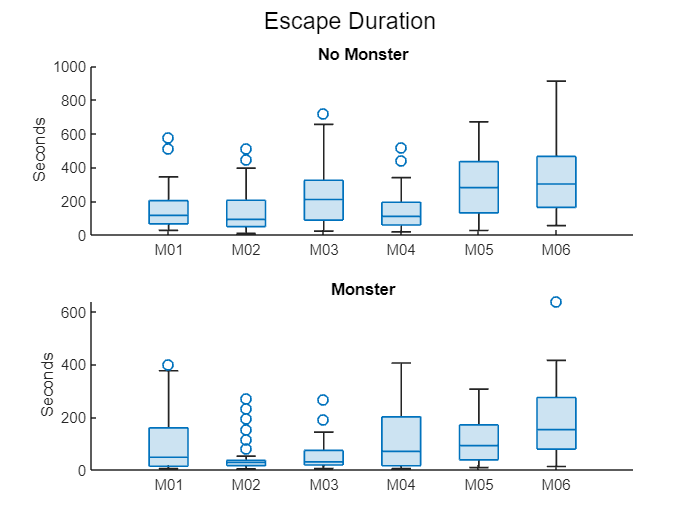

figure
no_monster_escape_duration_per_animal = [
    M01.no_monster_escape_duration_all, ...
    M02.no_monster_escape_duration_all, ...
    M03.no_monster_escape_duration_all, ...
    M04.no_monster_escape_duration_all, ...
    M05.no_monster_escape_duration_all, ...
    M06.no_monster_escape_duration_all
];

monster_escape_duration_per_animal = [
    M01.monster_escape_duration_all, ...
    M02.monster_escape_duration_all, ...
    M03.monster_escape_duration_all, ...
    M04.monster_escape_duration_all, ...
    M05.monster_escape_duration_all, ...
    M06.monster_escape_duration_all
];

subplot(2,1,1)
boxchart(no_monster_escape_duration_per_animal)
title("No Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

subplot(2,1,2)
boxchart(monster_escape_duration_per_animal)
title("Monster")
ylabel("Seconds")
xticklabels(["M01" "M02" "M03" "M04" "M05" "M06"])

sgtitle("Escape Duration")

function plot_mean_and_shaded_std(subplotpos, plottitle, argmean, argstdev, group)
    if (group == 1) 
        color = "#7E2F8E";
    end
    if (group == 2) 
        color = "#77AC30";
    end
    above = argmean + argstdev;
    below = argmean - argstdev;
    x = 1:7;
    x2 = [x, fliplr(x)];
    inBetween = [above, fliplr(below)];
    subplot(3,2,subplotpos)
    shaded = fill(x2, inBetween, "b", "FaceAlpha","0.2", "EdgeColor","none");
    shaded.FaceColor = color;
    hold on
    title(plottitle);
    ylabel("seconds")
    meanline = plot(argmean);
    meanline.Color = color;
    xticklabels(["" "M" "M" "M" ""])
    hold off
end

function plot_boxplot_across_sessions(subplotpos, plottitle, full_vector, group)    
    if (group == 1) 
        color = "#7E2F8E";
    end
    if (group == 2) 
        color = "#77AC30";
    end    
    subplot(3,2,subplotpos)
    boxchartvar = boxchart(full_vector);
    boxchartvar.BoxFaceColor = color;
    boxchartvar.BoxEdgeColor = color;
    boxchartvar.MarkerColor = color;
    title(plottitle)
    xticklabels(["" "M" "" "M" "" "M" ""])
end 

function plotgroup(animal_struct, meantoplot)
    group = animal_struct.animal_group;   
    if (group == 1) 
        color = "#7E2F8E";
    end
    if (group == 2) 
        color = "#77AC30";
    end    
    meanplot = plot(meantoplot);
    meanplot.Color = color;
    ylabel("seconds")
    xlabel("session")
    xticklabels(["" "M" "" "M" "" "M" ""])
end

function create_leg(leg)
    legend(leg, "Location","northeastoutside", "EdgeColor","none")
end